# Call Python from MATLAB 

**Goal:** Use Python code to import current weather data from the web. Predict air quality using MATLAB machine learning model.

## Part 1: Call Python from MATLAB

### Setup

Ensure Python is installed and confirm the version with [`pyenv`](https://mathworks.com/help/matlab/ref/pyenv.html). 

We will provide the path to the correct executable for MATLAB Online.

% pyenv
% pyenv("Version","/usr/bin/python3")   % for MATLAB Online

*Note: you may need to restart MATLAB if you've already run pyenv *

*Use pyversion prior to R2019b.*

*Note: Consider your directories and path needs - often we need to add our directories to both MATLAB and Python paths. *

## 1. Call Python Built-in Functions

Call Python functions using **py.** notation:

Test a simple function.

py.math.sqrt(42)

ans = 6.4807

You can create Python data structures inside MATLAB and call Python methods on them.

py.list({1,2,'a','b'})

ans =   Python list with no properties.

    [1.0, 2.0, 'a', 'b']

Before release 2022a, you pass name=value arguments using `pyargs`. For example, adapt the following Python syntax to be called from MATLAB.

*Hint: Consider default and expected data types*

py.textwrap.wrap("Hello world!",pyargs("width",int8(2)))    

ans =   Python list with no properties.

    ['He', 'll', 'o ', 'wo', 'rl', 'd!']

### Exercise: Call a built-in Python function

Try out some more Python built-in functions below:

% % Enter code here


py.help('list')

Help on class list in module builtins:

class list(object)
 |  list(iterable=(), /)
 |  
 |  Built-in mutable sequence.
 |  
 |  If no argument is given, the constructor creates a new empty list.
 |  The argument must be an iterable if specified.
 |  
 |  Methods defined here:
 |  
 |  __add__(self, value, /)
 |      Return self+value.
 |  
 |  __contains__(self, key, /)
 |      Return key in self.
 |  
 |  __delitem__(self, key, /)
 |      Delete self[key].
 |  
 |  __eq__(self, value, /)
 |      Return self==value.
 |  
 |  __ge__(self, value, /)
 |      Return self>=value.
 |  
 |  __getattribute__(self, name, /)
 |      Return getattr(self, name).
 |  
 |  __getitem__(...)
 |      x.__getitem__(y) <==> x[y]
 |  
 |  __gt__(self, value, /)
 |      Return self>value.
 |  
 |  __iadd__(self, value, /)
 |      Implement self+=value.
 |  
 |  __imul__(self, value, /)
 |      Implement self*=value.
 |  
 |  __init__(self, /, *args, **kwargs)
 |      Initialize self.  See help(type(self))

py.importlib.import_module('this')

ans =   Python module with properties:

    i: [1×1 py.int]
    s: [1×856 py.str]
    d: [1×1 py.dict]
    c: [1×1 py.int]
    <module 'this' from 'C:\\Python38\\Lib\\this.py'>

## 2. Call User Defined Python Code

There are several ways to call user-defined Python code from MATLAB, depending on how the code is prepared.

Use [`pyrun`](https://mathworks.com/help/matlab/ref/pyrun.html) to execute python statements and [`pyrunfile`](https://mathworks.com/help/matlab/ref/pyrunfile.html) to run a Python script file. 

### Run Python Script

First, examine the code then run the script using pyrunfile.

pyrunfile("weather_script.py")

Capture outputs from the script.

t = pyrunfile("weather_script.py","t")

Making small pizza with topping: pepperoni
The pizza costs 0.69


Making small pizza with topping: pepperoni
The pizza costs 0.14


x =   Python NoneType with no properties.

    None

### Exercise 2.1: Run Python Script

Modify `weather_script.py` line 21 to display info for a different city and call it from MATLAB.

% % Enter code here


Making small pizza with topping: pepperoni
The pizza costs 18.77


x =   Python NoneType with no properties.

    None

za =   Python str with no properties.

    pepperoni

### Call Python module

To call a module from MATLAB, we use this syntax

*Note: When you modify a module, you need to reload it for the changes to take effect. See the Appendix below for an example. *[*Reload Modified User-Defined Python Module - MATLAB & Simulink (mathworks.com)*](https://www.mathworks.com/help/matlab/matlab_external/call-modified-python-module.html)

### Call weather module

The `weather.py` module reads and parses current weather data from the web API by location: [https://openweathermap.org/api](https://openweathermap.org/api)

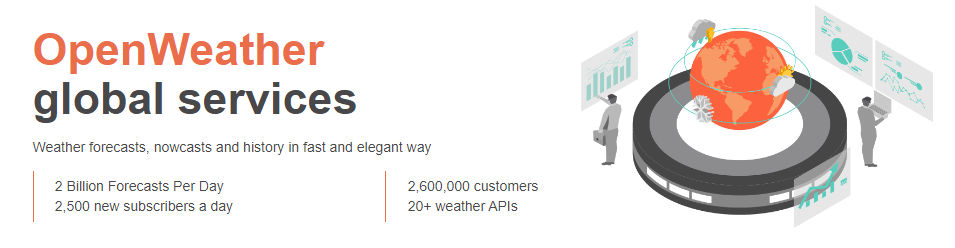

First, get the access key for the weather API.

apikey = readtable("accessKey.txt","TextType","string"); 

Use the `weather.py` module to get the air quality for Boston.

city = "Boston";
jsonData = py.weather.get_current_weather(city,"US",apikey.Key)

jsonData =   Python dict with no properties.

    {'coord': {'lon': -71.0598, 'lat': 42.3584}, 'weather': [{'id': 500, 'main': 'Rain', 'description': 'light rain', 'icon': '10d'}, {'id': 701, 'main': 'Mist', 'description': 'mist', 'icon': '50d'}], 'base': 'stations', 'main': {'temp': 38.8, 'feels_like': 28.2, 'temp_min': 36.82, 'temp_max': 40.23, 'pressure': 1022, 'humidity': 92}, 'visibility': 3219, 'wind': {'speed': 23.02, 'deg': 110}, 'rain': {'1h': 0.34}, 'clouds': {'all': 100}, 'dt': 1648127962, 'sys': {'type': 2, 'id': 2013408, 'country': 'US', 'sunrise': 1648118433, 'sunset': 1648162819}, 'timezone': -14400, 'id': 4930956, 'name': 'Boston', 'cod': 200}

Parse the json data returned from the weather API.

weatherData = py.weather.parse_current_json(jsonData)

weatherData =   Python dict with no properties.

    {'temp': 38.8, 'feels_like': 28.2, 'temp_min': 36.82, 'temp_max': 40.23, 'pressure': 1022, 'humidity': 92, 'speed': 23.02, 'deg': 110, 'lon': -71.0598, 'lat': 42.3584, 'city': 'Boston', 'current_time': '2022-03-24 09:22:35.610944'}

Extract the values from the dictionary. 

weatherData{'temp'}

ans = 38.8000

### Exercise: What is the forecast? 

Now, use the following syntax to call the` get_forecast` function from the weather module

% % Enter code here


Note the data types returned, which we will examine next.

## 3. Convert to MATLAB Data Types

Now we want to operate on this data in MATLAB, so the next step is to convert the data types as needed.

### Convert weather data

Now, we'll get back to converting our weather data. The weather data was a dictionary.

weatherData

weatherData =   Python dict with no properties.

    {'temp': 38.8, 'feels_like': 28.2, 'temp_min': 36.82, 'temp_max': 40.23, 'pressure': 1022, 'humidity': 92, 'speed': 23.02, 'deg': 110, 'lon': -71.0598, 'lat': 42.3584, 'city': 'Boston', 'current_time': '2022-03-24 09:22:35.610944'}

The **Python dictionary** can be represented as a **MATLAB struct**.

data = struct(weatherData)

data = struct with fields:
            temp: 38.8000
      feels_like: 28.2000
        temp_min: 36.8200
        temp_max: 40.2300
        pressure: [1×1 py.int]
        humidity: [1×1 py.int]
           speed: 23.0200
             deg: [1×1 py.int]
             lon: -71.0598
             lat: 42.3584
            city: [1×6 py.str]
    current_time: [1×26 py.str]

Convert the Python types within the struct to the desired MATLAB data types.

data.pressure = double(data.pressure);
data.city = string(data.city)

data = struct with fields:
            temp: 38.8000
      feels_like: 28.2000
        temp_min: 36.8200
        temp_max: 40.2300
        pressure: 1022
        humidity: [1×1 py.int]
           speed: 23.0200
             deg: [1×1 py.int]
             lon: -71.0598
             lat: 42.3584
            city: "Boston"
    current_time: [1×26 py.str]

### Exercise: Convert data types

Convert remaining Python types to MATLAB types.

% % Enter code here


### Predict air quality

Perform the remaining conversions and create a table using the function provided to prep for machine learning.

currentData = prepData(weatherData)

currentData = 1×12 table
         DateLocal            city        StateName       T       P       DP      RH    WindDir    WindSpd     yy     MM    dd
    ____________________    ________    _____________    ____    ____    _____    __    _______    _______    ____    __    __
    24-Mar-2022 09:22:35    "Boston"    Massachusetts    38.8    1022    35.92    92      110       23.02     2022    3     24

A machine learning model has been trained and validated on a large amount of historical climate data. The model is then saved as a .mat file. 

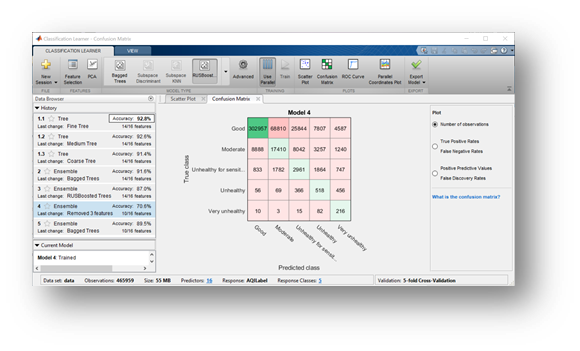

Use the model to predict the air quality for the new weather data.

load airQualModel 

airQual = predict(model,currentData)

airQual = categorical
     Good 

### Exercise: Predict air quality

Test the prediction code in MATLAB for different locations.

city = "Boston";
jsonData = py.weather.get_current_weather(city,"US",apikey.Key);
weatherData = py.weather.parse_current_json(jsonData)

weatherData =   Python dict with no properties.

    {'temp': 38.8, 'feels_like': 28.2, 'temp_min': 36.82, 'temp_max': 40.23, 'pressure': 1022, 'humidity': 92, 'speed': 23.02, 'deg': 110, 'lon': -71.0598, 'lat': 42.3584, 'city': 'Boston', 'current_time': '2022-03-24 09:22:41.071404'}

predictAirQual(weatherData)

ans = 'Good'

## 5. Handle timeseries (arrays) with the weather forecast

Now let's look at the weather forecast for this week in Boston!

jsonData = py.weather.get_forecast("Boston","US",apikey.Key);
forecastData = py.weather.parse_forecast_json(jsonData);
forecast = struct(forecastData)

forecast = struct with fields:
    current_time: [1×40 py.list]
            temp: [1×40 py.list]
             deg: [1×40 py.list]
           speed: [1×40 py.list]
        humidity: [1×40 py.list]
        pressure: [1×40 py.list]

The type of data returned by the parsed forecast date is a **Python list**:

forecast.temp

ans =   Python list with no properties.

    [38.93, 40.23, 42.69, 42.93, 42.8, 42.53, 40.24, 39.13, 47.25, 55.06, 54.68, 49.8, 46.58, 45.01, 41.23, 42.46, 48.63, 49.39, 49.28, 42.96, 41.31, 38.28, 38.88, 37.4, 44.28, 46.65, 43.45, 36.14, 31.42, 28.45, 25.95, 24.49, 26.65, 29.01, 30.0, 26.19, 24.26, 22.3, 20.41, 20.93]

It can be converted to a matrix of doubles:

% tempForecast = double(forecast.temp)          % from an array
tempForecast = cell2mat(cell(forecast.temp))    % from a list before 2022a

tempForecast =    38.9300   40.2300   42.6900   42.9300   42.8000   42.5300   40.2400   39.1300   47.2500   55.0600   54.6800   49.8000   46.5800   45.0100   41.2300   42.4600   48.6300   49.3900   49.2800   42.9600   41.3100   38.2800   38.8800   37.4000   44.2800   46.6500   43.4500   36.1400   31.4200   28.4500   25.9500   24.4900   26.6500   29.0100   30.0000   26.1900   24.2600   22.3000   20.4100   20.9300


Transform **timestamp list** from Python in **MATLAB datetime**:

foreTime = cell(forecast.current_time);   % before 2022a
T = cellfun(@string,foreTime)

T = 1×40 string array
    "2022-03-24 15:00:00"    "2022-03-24 18:00:00"    "2022-03-24 21:00:00"    "2022-03-25 00:00:00"    "2022-03-25 03:00:00"    "2022-03-25 06:00:00"    "2022-03-25 09:00:00"    "2022-03-25 12:00:00"    "2022-03-25 15:00:00"    "2022-03-25 18:00:00"    "2022-03-25 21:00:00"    "2022-03-26 00:00:00"    "2022-03-26 03:00:00"    "2022-03-26 06:00:00"    "2022-03-26 09:00:00"    "2022-03-26 12:00:00"    "2022-03-26 15:00:00"    "2022-03-26 18:00:00"    "2022-03-26 21:00:00"    "2022-03-27 00:00:00"    "2022-03-27 03:00:00"    "2022-03-27 06:00:00"    "2022-03-27 09:00:00"    "2022-03-27 12:00:00"    "2022-03-27 15:00:00"    "2022-03-27 18:00:00"    "2022-03-27 21:00:00"    "2022-03-28 00:00:00"    "2022-03-28 03:00:00"    "2022-03-28 06:00:00"    "2022-03-28 09:00:00"    "2022-03-28 12:00:00"    "2022-03-28 15:00:00"    "2022-03-28 18:00:00"    "2022-03-28 21:00:00"    "2022-03-29 00:00:00"    "2022-03-29 03:00:00"    "2022-03-29 06:00:00"    "2022-03-29 09:00:00"   

% T = string(forecast.current_time)       % starting in 2022a, direct
% conversion

Convert T in datetime

time = datetime(T)

time = 1×40 datetime array
   24-Mar-2022 15:00:00   24-Mar-2022 18:00:00   24-Mar-2022 21:00:00   25-Mar-2022 00:00:00   25-Mar-2022 03:00:00   25-Mar-2022 06:00:00   25-Mar-2022 09:00:00   25-Mar-2022 12:00:00   25-Mar-2022 15:00:00   25-Mar-2022 18:00:00   25-Mar-2022 21:00:00   26-Mar-2022 00:00:00   26-Mar-2022 03:00:00   26-Mar-2022 06:00:00   26-Mar-2022 09:00:00   26-Mar-2022 12:00:00   26-Mar-2022 15:00:00   26-Mar-2022 18:00:00   26-Mar-2022 21:00:00   27-Mar-2022 00:00:00   27-Mar-2022 03:00:00   27-Mar-2022 06:00:00   27-Mar-2022 09:00:00   27-Mar-2022 12:00:00   27-Mar-2022 15:00:00   27-Mar-2022 18:00:00   27-Mar-2022 21:00:00   28-Mar-2022 00:00:00   28-Mar-2022 03:00:00   28-Mar-2022 06:00:00   28-Mar-2022 09:00:00   28-Mar-2022 12:00:00   28-Mar-2022 15:00:00   28-Mar-2022 18:00:00   28-Mar-2022 21:00:00   29-Mar-2022 00:00:00   29-Mar-2022 03:00:00   29-Mar-2022 06:00:00   29-Mar-2022 09:00:00   29-Mar-2022 12:00:00

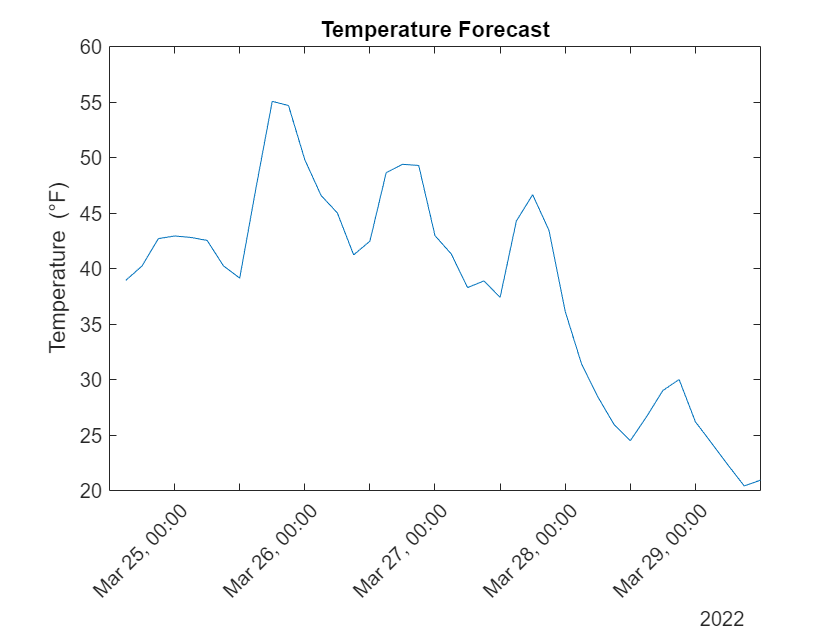

plot(time,tempForecast)
xtickangle(45)
title("Temperature Forecast")
ylabel("Temperature (\circF)")

### Bonus: Preprocess data using Live Editor Tasks

Weather forecasts are only provided every 4 hours. We want to retime to have data interpolated every single hour.

foreTemp = timetable(time',tempForecast','VariableNames',{'Temperature'});

% Retime timetable
newTimetable = retime(foreTemp,"regular","spline","TimeStep",hours(3))

newTimetable = 40×1 timetable
            Time            Temperature
    ____________________    ___________
    24-Mar-2022 15:00:00       38.93   
    24-Mar-2022 18:00:00       40.23   
    24-Mar-2022 21:00:00       42.69   
    25-Mar-2022 00:00:00       42.93   
    25-Mar-2022 03:00:00        42.8   
    25-Mar-2022 06:00:00       42.53   
    25-Mar-2022 09:00:00       40.24   
    25-Mar-2022 12:00:00       39.13   
    25-Mar-2022 15:00:00       47.25   
    25-Mar-2022 18:00:00       55.06   
    25-Mar-2022 21:00:00       54.68   
    26-Mar-2022 00:00:00        49.8   
    26-Mar-2022 03:00:00       46.58   
    26-Mar-2022 06:00:00       45.01   
    26-Mar-2022 

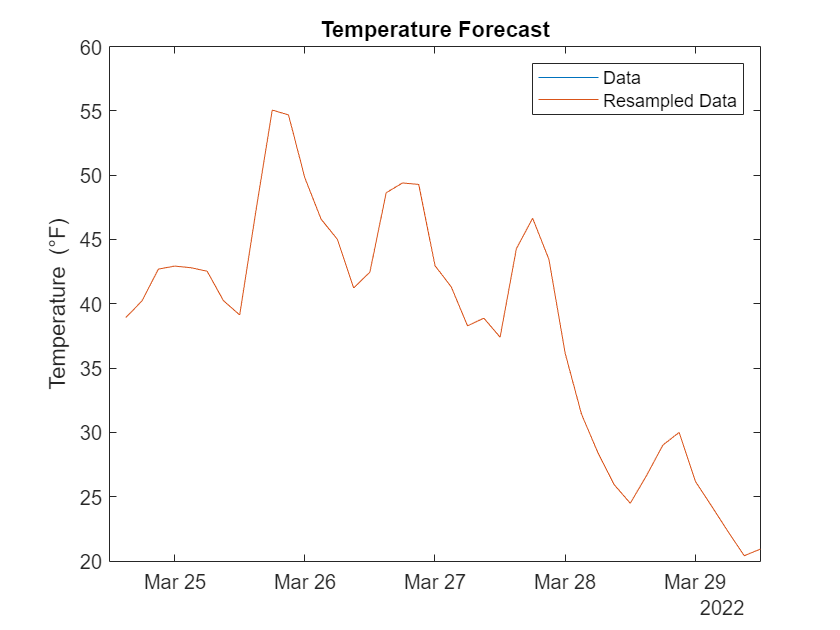

plot(foreTemp.Time,foreTemp.Temperature); hold on
plot(newTimetable.Time,newTimetable.Temperature); hold off
legend("Data","Resampled Data")
title("Temperature Forecast")
ylabel("Temperature (\circF)")

Select different trend removal parameters and examine the results.

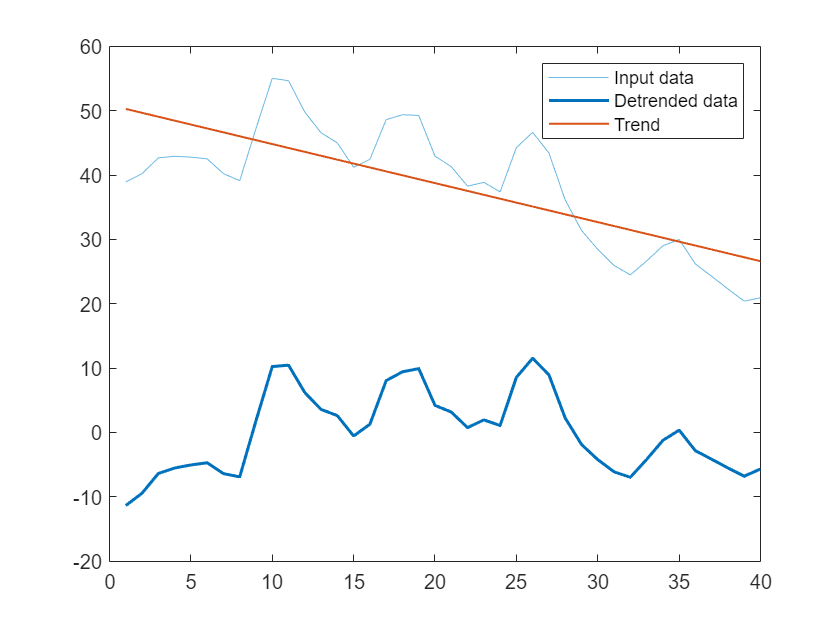

% Remove trend from data
detrendedData = detrend(tempForecast);

% Display results
clf
plot(tempForecast,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(detrendedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Detrended data')
plot(tempForecast-detrendedData,'Color',[217 83 25]/255,'LineWidth',1,...
    'DisplayName','Trend')
hold off
legend

There are a number of Live Editor Tasks you can add to this script to continue to clean the data (smooth, remove outliers, etc.). Try these out for yourself!

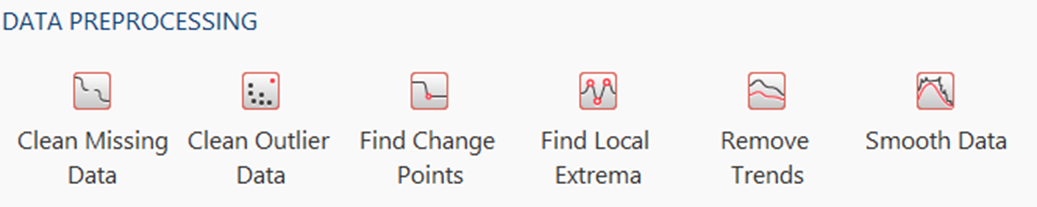

## Part 2: Call MATLAB prediction code from Python

Call a function capturing these steps and the correct data conversions to be called in the Python environment to predict the air quality.

% edit("predictAirQual.m")

Next, we will call this code from Python. See `CallMATLABfromPython.ipynb `

## Appendix

To reload Python module

Reload *weather.py *after modifications:

% clear classes
% mod = py.importlib.import_module('weather'); 
% py.importlib.reload(mod); 

Read the documentation to know more:

[Reload Modified User-Defined Python Module - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/matlab/matlab_external/call-modified-python-module.html)

*Copyright 2022 The MathWorks, Inc.*